在单 CPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０４　｜　　　４０．００％　｜　　５１．２２％　｜　　１．４８０２　｜　１．２８２０　｜　　０．０００３　｜
｜　　　１　｜　　　　５　｜　　　　　００：００：０８　｜　　　６０．００％　｜　　５９．７６％　｜　　０．５２９８　｜　０．８８４７　｜　　０．０００３　｜
｜　　　１　｜　　　１０　｜　　　　　００：００：１４　｜　　　６０．００％　｜　　５０．００％　｜　　１．０６３９　｜　２．５８９４　｜　　０．０００３　｜
｜　　　２　｜　　　１５　｜　　　　　００：００：１９　｜　　　６０．００％　｜　　５９．７６％　｜　　２．３２０４　｜　０．９３６８　｜　　０．０００３　｜
｜　　　２　｜　　　２０　｜　　　　　００：００：２４　｜　　１００．００％　｜　　６０．９８％　｜　　０．０５２２　｜　１．２２０６　｜　　０．０００３　｜
｜　　　３　｜　　　２５　｜　　　　　００：００：３０　｜　　　８０．００％　｜　　７５．６１％　｜　　１．１８３４　｜　１．１０５３　｜　　０．０００３　｜
｜　　　３　｜　　　３０　｜　　　　　００：００：３５　｜　　　７３．３３％　｜　　８６．５９％　｜　　１．２７９５　｜　０．４４１３　｜　　０．０００３　｜
｜　　　３　｜　　　３５　｜　　　　　００：００：４１　｜　　　７３．３３％　｜　　８７．８０％　｜　　０．９１１７　｜　０．４２１６　｜　　０．０００３　｜
｜　　　４　｜　　　４０　｜

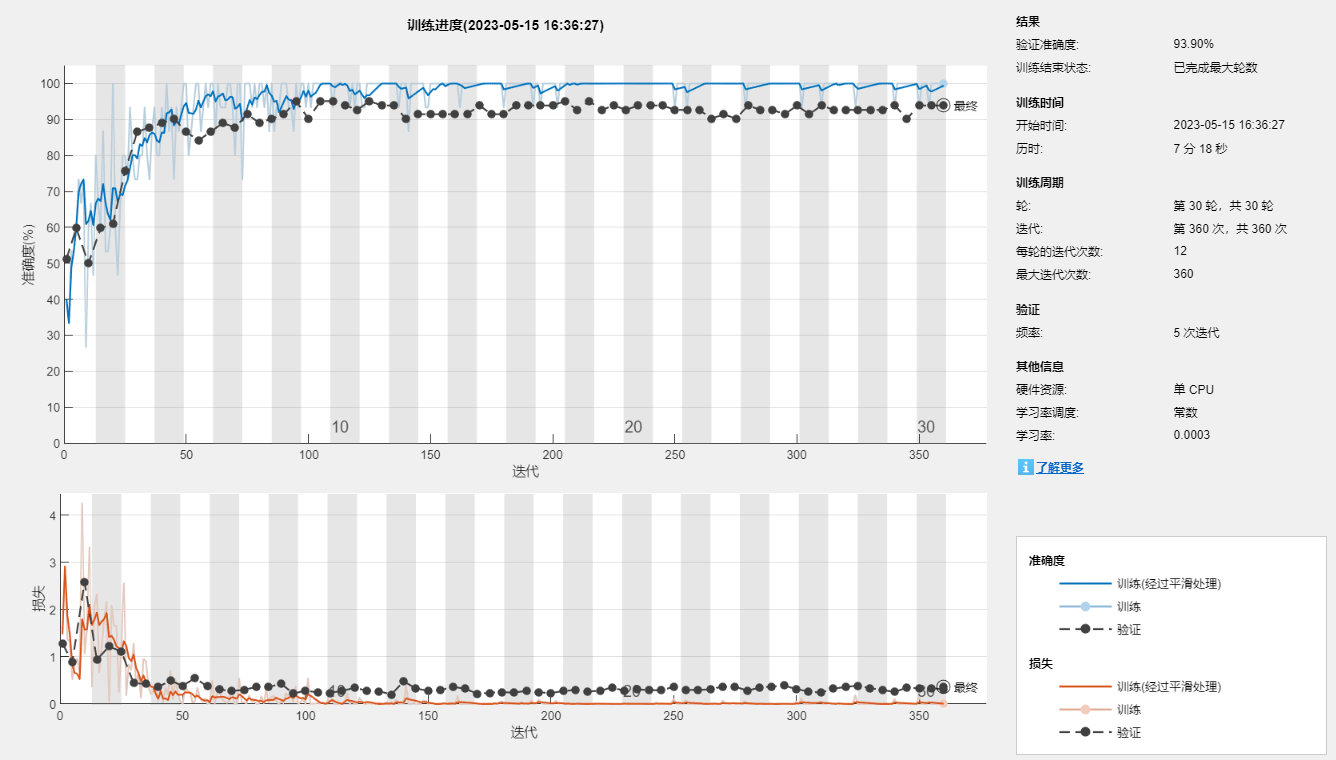

% 功能：对AlexNet用样本数据进行训练，实现对输入图像的识别
clear
close all
clc
% 加载图像数据
digitDatasetPath = fullfile('C:\Users\zorya triglav\Desktop\新建文件夹 (2)');
imds = imageDatastore(digitDatasetPath, ...
       'IncludeSubfolders',true, ...
       'LabelSource','foldernames');
 
% 划分验证集和训练集
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');
 
% 确定训练数据中需要分类的种类
numClasses = numel(categories(imdsTrain.Labels));
 
% AlexNet网络
alexnet = [
    imageInputLayer([388,374,1])
    convolution2dLayer([11,11],48,'Padding','same','Stride',4)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(3,'Padding','same','Stride',2)
    convolution2dLayer([5,5],128,'Padding',2,'Stride',1)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(3,'Padding','same','Stride',2)
    convolution2dLayer([3 3],192,'Padding',1,'Stride',1)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([3 3],192,'Padding',1,'Stride',1)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([3 3],128,'Stride',1,'Padding',1)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(3,'Padding','same','Stride',2)
    fullyConnectedLayer(4096)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(numClasses)  % 将新的全连接层的输出设置为训练数据中的种类
    softmaxLayer                     % 添加新的Softmax层
    classificationLayer ];           % 添加新的分类层
 
 
% 对构建的网络进行可视化分析
lgraph = layerGraph(alexnet);
analyzeNetwork(lgraph)
%% 调整数据集
 
% 网络输入层的大小和通道数
inputSize = [388,374,1];
 
% 将批量训练图像的大小调整为与输入层的大小相同
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
% 将批量验证图像的大小调整为与输入层的大小相同
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
 
%% 对网络进行训练
 
% 对训练参数进行设置
options = trainingOptions('sgdm', ...
    'MiniBatchSize',15, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',0.0003, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',5, ...
    'Verbose',true, ...
    'Plots','training-progress');
 
% 用训练图像对网络进行训练
net = trainNetwork(augimdsTrain,alexnet,options);

 
%% 验证并显示结果
 
% 对训练好的网络采用验证数据集进行验证
[YPred,scores] = classify(net,augimdsValidation);
 
%% 计算分类准确率
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9390

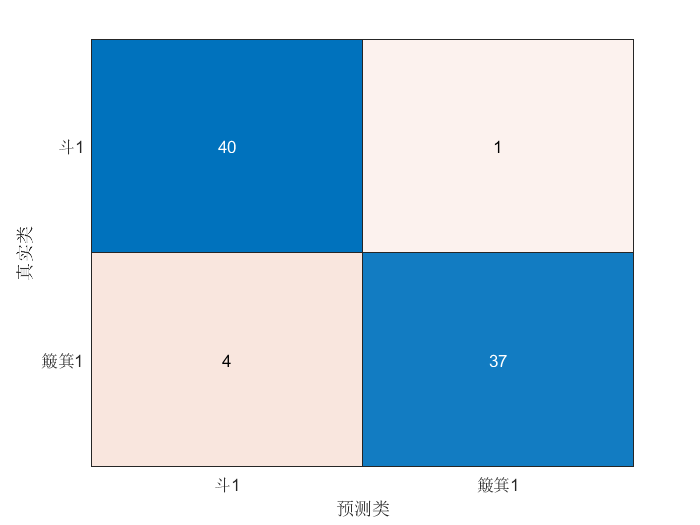

 
%% 创建并显示混淆矩阵
figure
confusionchart(YValidation,YPred)